close all; clear; clc;

# 2 bat test (KDE motor) 5 min run at 500 watts

**file name**: MEGA_temp_300W_2bat_5min_20190321.mlx

**keywords:** 

**date of test:** 201903

**file created by:** 20190403, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]


% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('MEGA_temp_300W_2bat_5min_20190321.mat');
time2 = MEGA_temp_300W_2bat_5min_20190321(:,1);                       % [sec]
PWM2 = MEGA_temp_300W_2bat_5min_20190321(:,2);                        % [micro sec]
ESC_Temp2 = MEGA_temp_300W_2bat_5min_20190321(:,14);                  % [F]
Motor_Temp2 = MEGA_temp_300W_2bat_5min_20190321(:,15);                % [F]
Input_V2 = MEGA_temp_300W_2bat_5min_20190321(:,6);                    % [Volts]
Input_A2 = MEGA_temp_300W_2bat_5min_20190321(:,7);                    % [Amps]
rot_speed_rpm2 = MEGA_temp_300W_2bat_5min_20190321(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad2 = rot_speed_rpm2 .* (pi/30);   % [rad/sec]
P_in_W2 = MEGA_temp_300W_2bat_5min_20190321(:,9);                     % [Watts]
P_out_W2 = MEGA_temp_300W_2bat_5min_20190321(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out2 = P_out_W2 .* 0.7478;                  % [ft.lbf/sec]         
P_in2 = P_in_W2 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff2 = MEGA_temp_300W_2bat_5min_20190321(:,11);                 % [%]
maxT2 = max(Motor_Temp2)

maxT2 = 75.9875

avg2 = mean(Input_V2)

avg2 = 23.8090


load('MEGA_temp_300W_3bat_5min_20190321.mat');
time3 = MEGA_temp_300W_3bat_5min_20190321(:,1);                       % [sec]
PWM3 = MEGA_temp_300W_3bat_5min_20190321(:,2);                        % [micro sec]
ESC_Temp3 = MEGA_temp_300W_3bat_5min_20190321(:,14);                  % [F]
Motor_Temp3 = MEGA_temp_300W_3bat_5min_20190321(:,15);                % [F]
Input_V3 = MEGA_temp_300W_3bat_5min_20190321(:,6);                    % [Volts]
Input_A3 = MEGA_temp_300W_3bat_5min_20190321(:,7);                    % [Amps]
rot_speed_rpm3 = MEGA_temp_300W_3bat_5min_20190321(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad3 = rot_speed_rpm3 .* (pi/30);   % [rad/sec]
P_in_W3 = MEGA_temp_300W_3bat_5min_20190321(:,9);                     % [Watts]
P_out_W3 = MEGA_temp_300W_3bat_5min_20190321(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out3 = P_out_W3 .* 0.7478;                  % [ft.lbf/sec]         
P_in3 = P_in_W3 .* 0.7478;                    % [ft.lbf/sec]
maxT3 = max(Motor_Temp3)

maxT3 = 77.1125

avg3 = mean(Input_V3)

avg3 = 35.7062


load('MEGA_temp_300W_4bat_5min_20190321.mat');
time4 = MEGA_temp_300W_4bat_5min_20190321(:,1);                       % [sec]
PWM4 = MEGA_temp_300W_4bat_5min_20190321(:,2);                        % [micro sec]
ESC_Temp4 = MEGA_temp_300W_4bat_5min_20190321(:,14);                  % [F]
Motor_Temp4 = MEGA_temp_300W_4bat_5min_20190321(:,15);                % [F]
Input_V4 = MEGA_temp_300W_4bat_5min_20190321(:,6);                    % [Volts]
Input_A4 = MEGA_temp_300W_4bat_5min_20190321(:,7);                    % [Amps]
rot_speed_rpm4 = MEGA_temp_300W_4bat_5min_20190321(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad4 = rot_speed_rpm4 .* (pi/30);   % [rad/sec]
P_in_W4 = MEGA_temp_300W_4bat_5min_20190321(:,9);                     % [Watts]
P_out_W4 = MEGA_temp_300W_4bat_5min_20190321(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out4 = P_out_W4 .* 0.7478;                  % [ft.lbf/sec]         
P_in4 = P_in_W4 .* 0.7478;                    % [ft.lbf/sec]
maxT4 = max(Motor_Temp4)

maxT4 = 78.6875

## Plots

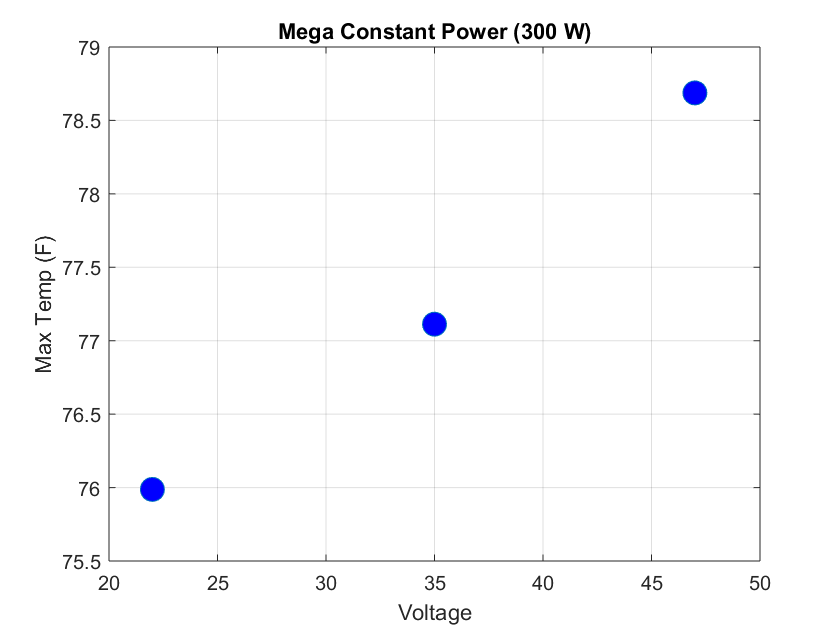

figure(1)
plot([22 35 47], [maxT2 maxT3 maxT4], 'o', 'MarkerSize', 12, 'MarkerFaceColor','b');
grid('on'); 
title('Mega Constant Power (300 W)');
xlabel('Voltage'); ylabel('Max Temp (F)');